%clearing
clear;
clc;
close all;

%excel file import
filename = 'fulldata.xlsx';
cdata = readmatrix(filename);
disp(size(cdata));

   120    10




cdata1 = cdata(:,:);

returns = diff(cdata1) ./ cdata1(1:end-1, :);

range0 = returns(1:59,:);
range1 = returns(60:71,:);
n = length(range1);

%Performing PCA on both ranges
%standardization range0
data_mean0 = mean(range0);
data_std0 = std(range0);
data_standardized0 = (range0 - data_mean0) ./ data_std0;

data_mean1 = mean(range1);
data_std1 = std(range1);
data_standardized1 = (range1 - data_mean1) ./ data_std1;


% Perform PCA
[coeff0, score0, latent0, explained0] = pca(data_standardized0);
[coeff1, score1, latent1, explained1] = pca(data_standardized1);

% Determine the number of components to retain (e.g., 90% variance explained)
cumulative_explained0 = cumsum(explained0);
num_components0 = find(cumulative_explained0 >= 95, 1);
disp(num_components0);

     8



reduced_data0 = score0(:, 1:num_components0);

cumulative_explained1 = cumsum(explained1);
num_components1 = find(cumulative_explained1 >= 95, 1);
disp(num_components1);

    10



reduced_data1 = score1(:, 1:num_components1);
%reconstruct data set
reconstructed_data_standardized0 = reduced_data0 * coeff0(:, 1:num_components0)';
reconstructed_data_standardized1 = reduced_data1 * coeff1(:, 1:num_components1)';

%reverse standardization
reconstructed_data0 = reconstructed_data_standardized0 .* data_std0 + data_mean0;
reconstructed_data1 = reconstructed_data_standardized1 .* data_std1 + data_mean1;

%perform bayesian update

Sigma0 = cov(reconstructed_data0);
Sigma1 = cov(range1);

mu0 = mean(reconstructed_data0)';
mu1 = mean(range1)';
n = 12;

% Calculate the inverse of Sigma0 and Sigma1
Sigma0_inv = inv(Sigma0);

Sigma1_inv = inv(Sigma1);

% Calculate the inverse of (Sigma0_inv + n*Sigma1_inv)
Sigma_star_inv = Sigma0_inv + n * Sigma1_inv;
Sigma_star = inv(Sigma_star_inv);

% Calculate mu_star
mu_star = Sigma_star * (Sigma0_inv * mu0 + n * Sigma1_inv * mu1);
num_assets = size(mu_star, 1);

% Display the results
disp('mu_star:');

mu_star:


disp(mu_star);

   -0.0024
   -0.0066
    0.0194
    0.0535
    0.0004
    0.0095
   -0.0061
   -0.0045
   -0.0164
   -0.0188



disp('Sigma_star:');

Sigma_star:


disp(Sigma_star);

   1.0e-03 *

    0.1110   -0.0864    0.0400    0.0363    0.0735    0.0331    0.0385    0.0429    0.0374    0.0533
   -0.0864    0.3648    0.0805    0.1333    0.0920    0.0440    0.1173    0.1202    0.2448    0.1966
    0.0400    0.0805    0.1823    0.1525    0.1140    0.0544    0.0865    0.1226    0.1228    0.1447
    0.0363    0.1333    0.1525    0.4695    0.1870    0.0610    0.0866    0.0623    0.0990    0.0900
    0.0735    0.0920    0.1140    0.1870    0.1546    0.0587    0.0988    0.1124    0.1498    0.1503
    0.0331    0.0440    0.0544    0.0610    0.0587    0.0655    0.0567    0.0480    0.0686    0.0647
    0.0385    0.1173    0.0865    0.0866    0.0988    0.0567    0.1039    0.1264    0.1739    0.1661
    0.0429    0.1202    0.1226    0.0623    0.1124    0.0480    0.1264    0.1959    0.2243    0.2303
    0.0374    0.2448    0.1228    0.0990    0.1498    0.0686    0.1739    0.2243    0.3318    0.3087
    0.0533    0.1966    0.1447    0.0900    0.1503    0.0647    0.1661    0.2

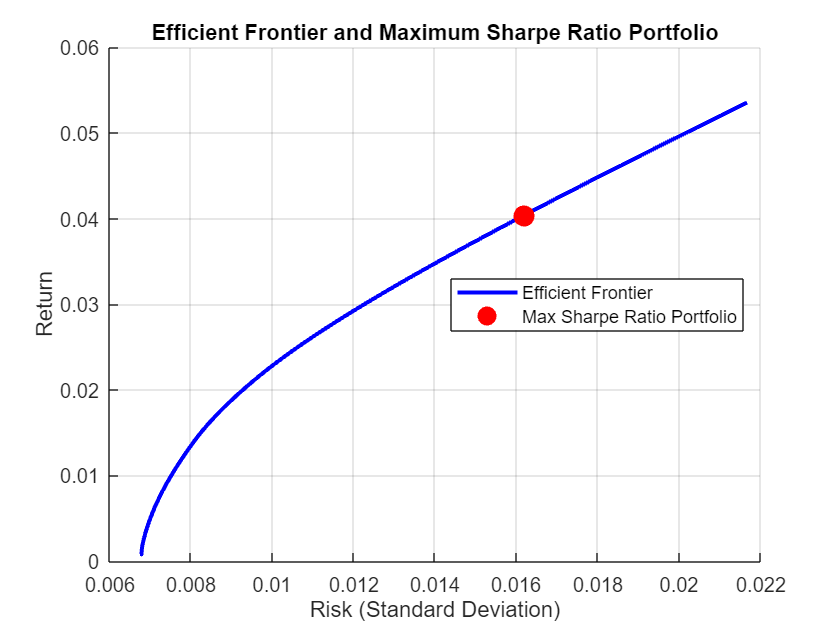


rowSum = sum(Sigma_star);
rowmean = mu_star';
% rf rate for sharpe calculation
rf = 0.00;
shortselltoggle = 0;
% we aim to find the lowest risk possible for each interval between
% returns. Accuracy increases with the more number of portfolios.
target_returns = linspace(min(mu_star), max(mu_star), 100);

% Array setup
portfolio_risks = zeros(length(target_returns), 1);
portfolio_returns = zeros(length(target_returns), 1);
portfolio_weights = zeros(length(target_returns), num_assets);

% Solve the optimization problem for each linspaced return
options = optimoptions('quadprog', 'Display', 'off');
for i = 1:length(target_returns)
    target_return = target_returns(i);
    
    % Define the optimization problem
    f = zeros(num_assets, 1); %no constant
    Aeq = ones(1, num_assets); %sum(weights) ==1, we can change this to -1 to 1 to allow for shortselling
    beq = 1;
    A = -mu_star'; % mean return >= target return
    b = -target_return;
    if (shortselltoggle == 0    )
        lb = zeros(num_assets, 1);
        ub = ones(num_assets, 1);
    else
        lb = -1 *ones(num_assets, 1);
        ub = ones(num_assets, 1);
    end

    % Solve the quadratic programming problem
    [x, ~, solutionindicator] = quadprog(Sigma_star, f, A, b, Aeq, beq, lb, ub, [], options);
    
    if solutionindicator == 1 % Solution found
        portfolio_weights(i, :) = x';
        portfolio_returns(i) = mu_star' * x;
        portfolio_risks(i) = sqrt(x' * Sigma_star * x);
    else
        portfolio_weights(i, :) = NaN;
        portfolio_returns(i) = NaN;
        portfolio_risks(i) = NaN;
    end
end

% Remove NaN values
valid_indices = ~isnan(portfolio_returns);
portfolio_risks = portfolio_risks(valid_indices);
portfolio_returns = portfolio_returns(valid_indices);
portfolio_weights = portfolio_weights(valid_indices, :);

%find the sharpe ratios for each generated portfolio
sharpe_ratios = (portfolio_returns - rf) ./ portfolio_risks;

%locate portfolio with max sharpe ratio
[~, sharpehigh] = max(sharpe_ratios);
%return parameters
max_sharpe_weights = portfolio_weights(sharpehigh, :);
max_sharpe_return = portfolio_returns(sharpehigh);
max_sharpe_risk = portfolio_risks(sharpehigh);


%Efficient Frontier plot with risk free rate line (CML)
figure;
hold on;
plot(portfolio_risks, portfolio_returns, 'b-', 'LineWidth', 2);

plot(max_sharpe_risk, max_sharpe_return, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('Risk (Standard Deviation)');
ylabel('Return');
title('Efficient Frontier and Maximum Sharpe Ratio Portfolio');
legend('Efficient Frontier', 'Max Sharpe Ratio Portfolio', 'Location', 'Best');
grid on;


%
disp('weights for the high sharpe ratio portfolio');

weights for the high sharpe ratio portfolio


disp(max_sharpe_weights);

    0.0000    0.0000    0.0288    0.6947    0.0000    0.2765    0.0000    0.0000    0.0000    0.0000




disp(['Maximum Sharpe Ratio: ', num2str(sharpe_ratios(sharpehigh))]);

Maximum Sharpe Ratio: 2.4938


disp(['Expected Portfolio Return: ', num2str(max_sharpe_return)]);

Expected Portfolio Return: 0.040378


disp(['Portfolio Risk (Standard Deviation): ', num2str(max_sharpe_risk)]);

Portfolio Risk (Standard Deviation): 0.016191
